# Make movie with new structure

dataOut = dataOutYANG;

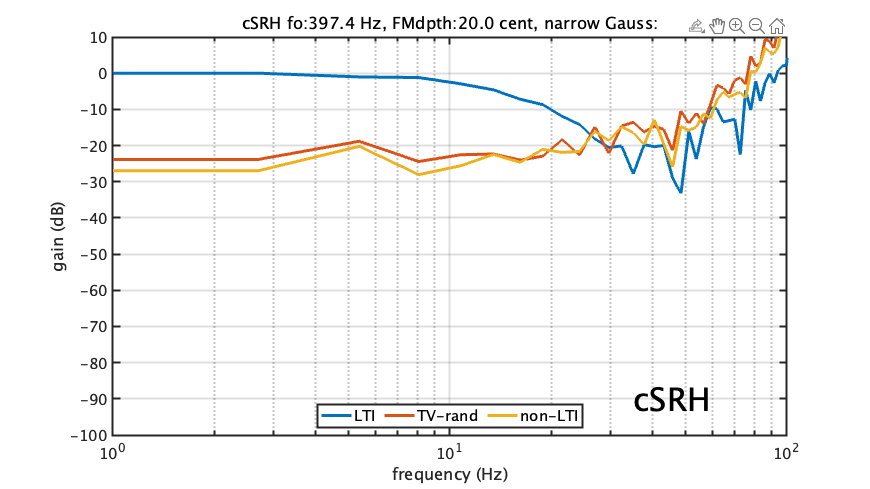

nFo = length(dataOut.fcList);
titleStr = 'cSRH';%output.testCondStr.titleStr;
foList = dataOut.fcList;%fl * 2 .^ (0:1/nOct:log2(fh/fl));
figure;
set(gcf, 'position', [681   700   960   540])
output = dataOut.frameStr;
fxSeg = output(1).fxSeg;
fxSeg(1) = fxSeg(2)/1000000;
for ii = 1:nFo
    output = dataOut.frameStr(ii);
    respLTI = 20*log10(abs(output.averageResponse));
    respTVI = 10*log10(output.varTV);
    respNLTI = 10*log10(output.varNLTI);
    semilogx(fxSeg, respLTI([2 2:end]), 'linewidth', 3);
    hold all;
    semilogx(fxSeg, respTVI([2 2:end]), 'linewidth', 3);
    semilogx(fxSeg, respNLTI([2 2:end]), 'linewidth', 3);
    grid on;
    set(gca, 'fontsize', 15, 'linewidth', 2)
    axis([1 100 -100 10])
    title(titleStr + " fo:" + num2str(foList(ii), '%7.1f') + " Hz, FMdpth:" ...
        + num2str(fmCent, '%7.1f') + " cent, narrow Gauss:");
    xlabel('frequency (Hz)')
    ylabel('gain (dB)')
    text(35, -90, titleStr, 'FontSize', 32)
    legend('LTI', 'TV-rand', 'non-LTI', 'location', 'south','Orientation','horizontal', 'fontsize', 15);
    drawnow
    hold off
end